# Simulating a multi-level dataset for linear mixed effects analysis

This tutorial takes a simulation-based approach to understanding mixed effects models.  We start with the fundamental equations specifying the model structure. Then, we simulate data with two variance components and fit several mixed effects models to it.

Why do we do this?  Even the most advanced users do not necessarily know the implications and effects of the assumptions and procedures used in modeling. A simulation-based approach allows you to interrogate how the model performs under different scenarios (i.e., data and experimental design conditions). This provides a way of understanding the models' behavior, including **bias**, **variance**, **power**, and **false positive rates**.

[This video](https://youtu.be/OL6UezgpmPo?list=PLB2iAtgpI4YEAUiEQ1ZnfMXY-yewNzn9z) on simulating mixed effects data by Jeanette Mumford is a clear and gentle introduction that might be helpful. It is part of the [Mumford mixed effects models series on Youtube](https://www.youtube.com/playlist?list=PLB2iAtgpI4YEAUiEQ1ZnfMXY-yewNzn9z).  She also has a [Mumford mixed models in fMRI series](https://www.youtube.com/playlist?list=PLB2iAtgpI4YFbAR9D4ZmWohRFXB3w5DWK).

### **Model formulation**

**First level:** 


$$Y_i =$$

$$Z_i \beta_i +\epsilon_i$$


This describes how individual-participant data are generated from a set of fixed predictors and participant-specific model parameters ("true" regression intercept and slope values for each participant). Outcome data vector $y\;$for participant $i$($y_i$) is generated by a within-person design matrix $Z_i$times participant-specific coefficient vector $\beta_i$ plus participant specific error vector $\epsilon_i$. 

-  $i=\left\lbrace 1\ldotp \ldotp \ldotp m\right\rbrace$, where $m$is the number of participants. 

- $y$ and $\epsilon_i$ are $n_i \;x\;1$vectors corresponding to $n_i$ observations

- $Z_i$is an $n_i \;x\;p\;$**design matrix** of $p\;$model predictors (regressors). $Z_i$ can vary across participants. $p$ has the same value for all participants. One column of $Z_i \;$is constant across all rows, and it's coefficient reflects the model intercept.

- $\beta_i$ is a $p\;x\;1\;$vector of participant-specific model parameters. Note that these are theoretical values, not estimates, as we are laying out the structure of the model.

**Second level**:


$$\beta_i =A\beta_G +\eta_i$$


This describes how participant-specific model parameters $\beta_i$ are generated from between-person (**g**roup-level) population-level model parameters $\beta_G$. $\beta_i$ is generated by a between-person design matrix $X_G$ (see below) times fixed population-level coefficient vector $\beta_G$ plus participant-specific deviation $\eta_i$. 

- $\beta_i$ is a $p\;x\;1\;$vector of participant-specific model parameters.

- $\beta_P$ is a $p\;x\;1\;$vector of fixed population-level model parameters.

- *A* is a placeholder identity matrix for group-level variables here, *eye(p)*

- $\eta_i$is a participant-specific deviation from population-level effects.  If participants are selected randomly from a population, $\eta_i$ varies randomly across $m$ levels, and introduces a **random effect**. 

**Combined two-level model **


$$\begin{array}{l}
Y_i =Z_i \left({\mathrm{X}}_G \beta_G +\eta_i \right)+\epsilon_i \;\\
Y_i =Z_i {\mathrm{X}}_G \beta_G +Z_i \eta_i +\epsilon_i 
\end{array}$$


$X_G$ is an $\textrm{mp}\;x\;p\;$**second-level** **design matrix** of between-person predictors for the intercept and other model parameters.  

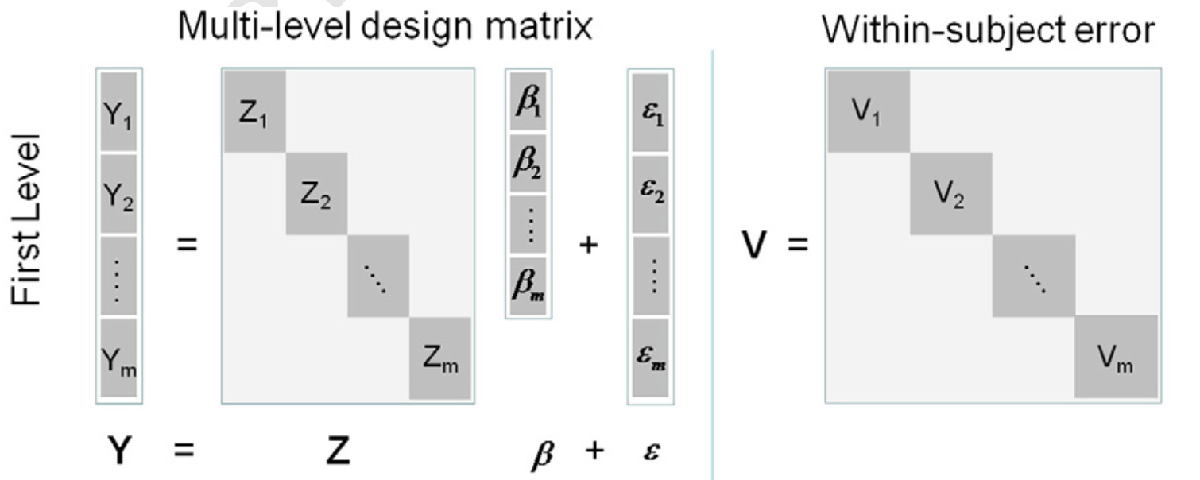

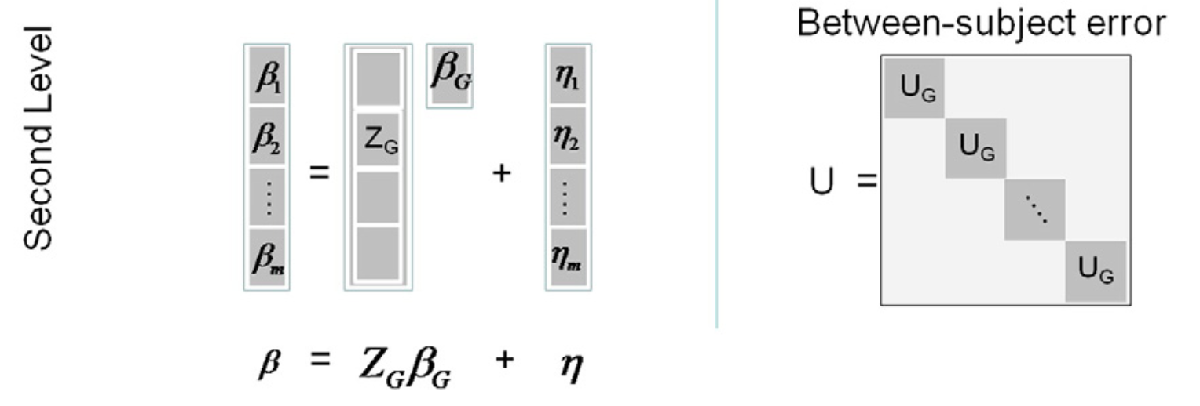

**Alternative notations**

There are several other notation systems that differ somewhat in the notation used. Here are the equations used in the Mumford video lectures.

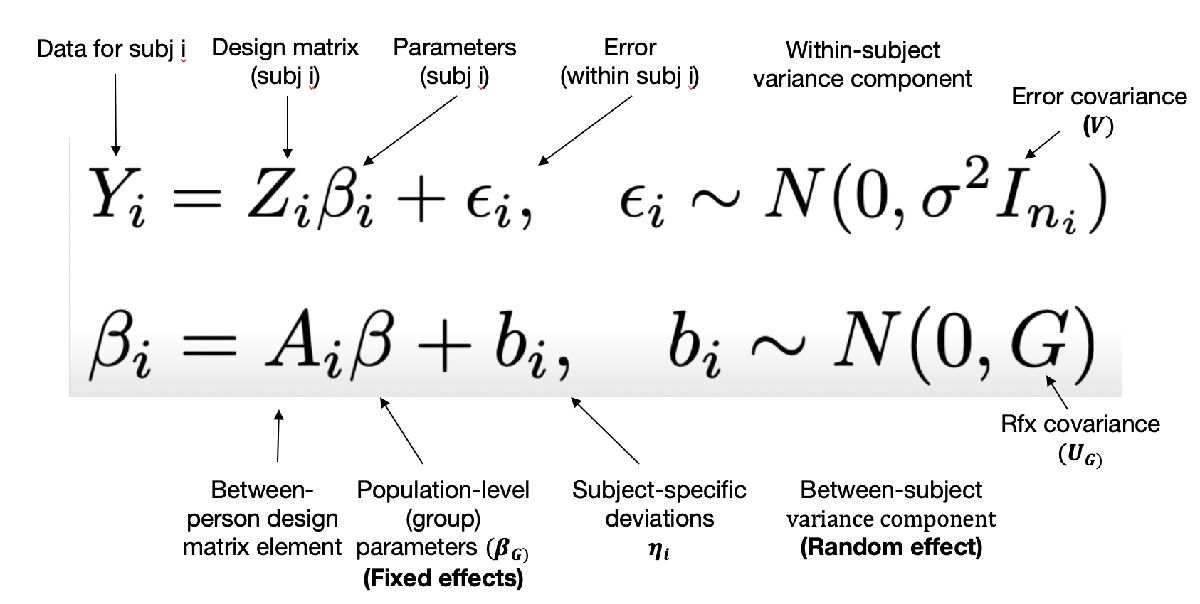

### Specify parameters and model structure


% number of subjects
m = 20;         

% n observations within-subject
% For now, assume same across all subjects

n_within =20; 

n_i = n_within * ones(m, 1); 

% Number of model parameters (regressors), including intercept
p = 2;

% Within-person residual noise variance
% For now, assume same across all subjects
sig_2_within =1.1;

% s2 is 1 x m vector of residual variances
s2 = sig_2_within .* ones(1, m);

**Fixed population-level effects**

Specify a column vector of true population-level values for each effect, intercept followed by other parameters.

b_g = [5 2]';

% Check the size 
if any(size(b_g) - [p 1])
    error('Population effects b_g is the wrong size')
end

**Group-level covariance matrix**

Diagonals are variances for each of p parameters. By convention, the intercept is first. 

Off-diagonals are covariances

e.g., for an intercept and slope (simple multilevel regression), U_g would be a 2 x 2 matrix with variances of the intercept and slope on the diagonal.


U_g = [20 0; 0 10];  

% Check the size 
if ~all(size(U_g) == p)
    error('Covariance matrix U_g is the wrong size')
end

%%

**Fixed design matrix**

These can be the same for all subjects, or different. They'd be the same if we were using a fixed experimental design with the same numbers of observations per person, and different if (1) our predictors are measured variables or (2) we have different numbers of observations. 

We'll assume they are the same across participants for now, but allow the code to be easily extended to different design matrices across participants.

Predictors can also be categorical or continuous, and correlated or uncorrelated. We'll generate a simple effects-coded [1 -1] predictor for now, with approximately balanced numbers of observations.

The intercept is first (a column of 1's) by convention.

Z_within = [ones(n_within, 1)]; % intercept

Z_tmp = randn(n_within, p - 1); 

Z_tmp(Z_tmp >= 0) = 1;
Z_tmp(Z_tmp <= 0) = -1;

Z_within = [Z_within Z_tmp];

Z_i = {};
for i = 1:m         % allows subjects to vary later if needed

    Z_i{i} = Z_within;

end


Now we have all the variables we need to simulate data:

n_i                         Number of observations for each person i = 1...m

b_g                        Population-level true fixed effects parameters 

s2                          residual variances for each person (1 x m)

U_g                        Group covariance matrix

Z_i                         Design matrix for each person

#### Questions to answer

Under most input parameter choices, the dataset will include a random subject intercept and random subject slope. 

Which input parameter would you change to make the dataset consistent with a "random intercept only" model?

Which input parameter would you change to make the dataset consistent with a "random slope only" model?

### **Create simulated dataset**

**Generate subject-level true parameters**

Assume a normal distribution with covariance  U_g

beta_i here is an [p x m] matrix where column i is the [p x 1] true beta coefficient vector for subject i.

beta_i = mvnrnd(b_g, U_g, m)';

**Generate data (y)**

y = cell(1, m);

for i = 1:m         

    y{i} = Z_i{i} * beta_i(:, i) + sqrt(s2(i)) .* randn(n_i(i), 1);

end

To fit the dataset, we'll need these variables:

y{i = 1...m}            The DV/outcome

Z_i{i = 1...m}         The design matrix for each person

CANlab functions like **glmfit_multilevel**, **igls**, and **rigls** can use these cell arrays directly.

For **fitlm** and **fitlme**, and **lmer** in R (etc.), we will want these in stacked, 'long format' tabular form for mixed effects models.  This requires a Grouping (in this case a Subject ID variable) as well. We will also create a column for each predictor and leave out the intercept, as it's added automatically.

% Make a long-format table with simulated data

sim_data = table(cat(1, y{:}), 'VariableNames', {'Y'});

sid_tmp = {}; % Subject ID
var_tmp = {}; % predictor variables

for i = 1:m         

    sid_tmp{i} = i .* Z_i{i}(:, 1);  % use intercept in case n's vary

    for j = 1:(p-1)

        var_tmp{j}{i} = Z_i{i}(:, j+1); 

    end

end

sim_data.sid = cat(1, sid_tmp{:});

% add other variables
for j = 1:(p-1)

    varname = sprintf('x%02d', j);
    sim_data.(varname) = cat(1, var_tmp{j}{:});

end

sim_data

sim_data = 400×3 table
      Y       sid       x01   
    ______    ___    _________

    15.034     1        0.7832
    14.554     1        -0.689
    17.276     1       0.70232
    15.752     1      -0.11426
    13.029     1      0.028593
    13.595     1         1.584
    15.471     1     -0.022887
    15.172     1       -1.3381
    15.045     1      -0.62975
    15.197     1       0.54235
    13.773     1       -1.3703
    14.808     1       0.19422
    16.448     1       0.47694
    13.345     1      -0.65938
    15.468     1        -0.546
    15.243     1      -0.47666


### Plot the dataset

For plotting, we may need to extract a predictor. This extracts the first non-intercept predictor (if p > 1 and there is one).

We'll use the CANlab function **line_plot_multisubject. **It gives us some output and basic stats on the relationship between x1 and y as well.

Warnings:

____________________________________________________________________________________________________________________________________________
Y: input cells with low varability:
19
____________________________________________________________________________________________________________________________________________

____________________________________________________________________________________________________________________________________________
Input data:
X scaling: No centering or z-scoring
Y scaling: No centering or z-scoring
                
Transformations:
No data transformations before plot
                                                                   
Correlations:                                                      
r = 0.14 across all observations, based on untransformed input data
                                                                
Stats on slopes after transformation, subject is random effect: 
Mean b = 0.97, t( 19) = 1.26, p = 0.

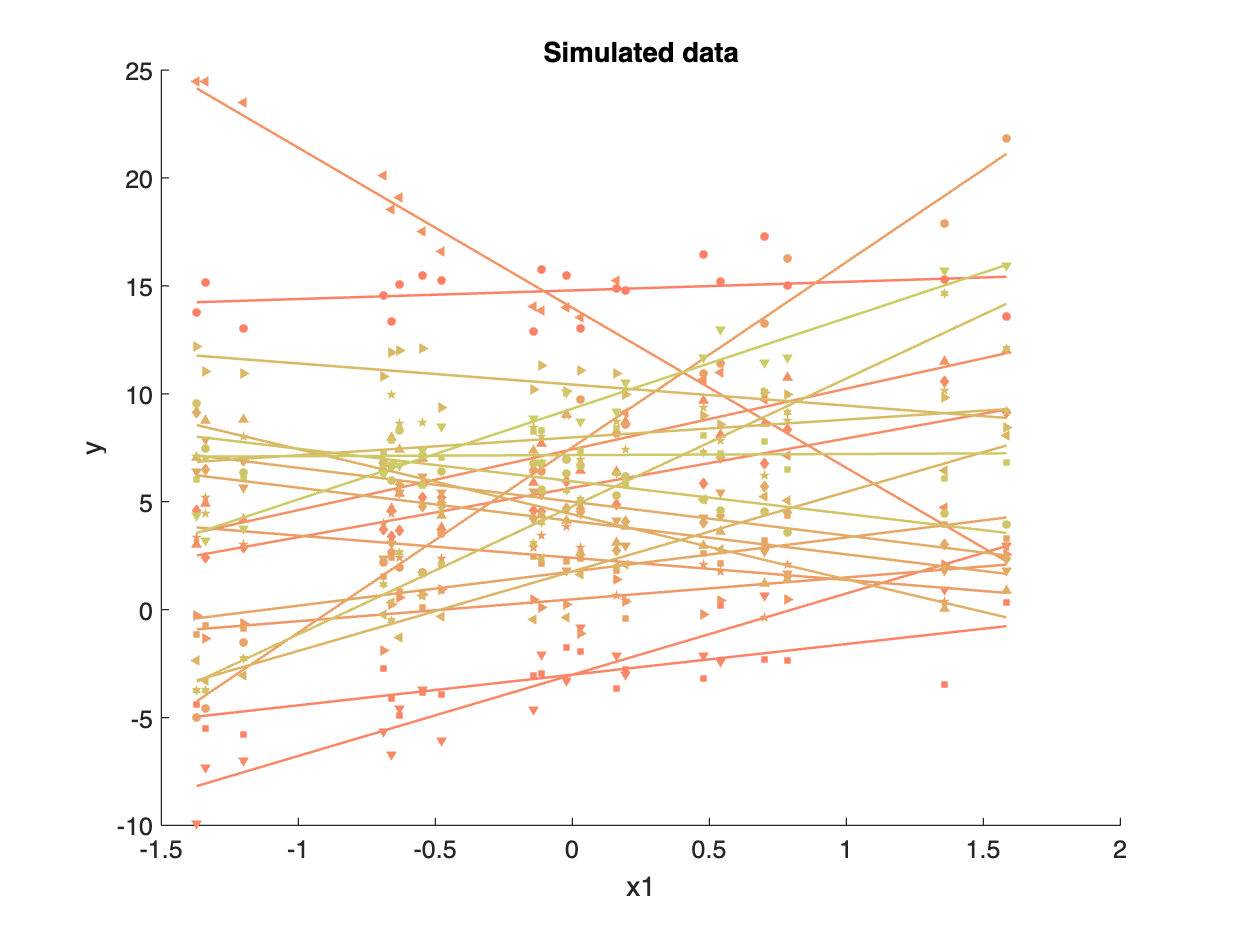

if p > 1
    x1 = cellfun(@(x) x(:, 2), Z_i, 'UniformOutput', false);

disp('line_plot_multisubject output:')
[han, ~, ~, slope_stats] = line_plot_multisubject(x1, y);

xlabel('x1')
ylabel('y')
title('Simulated data')

else
    disp('Intercept only: No x1-y relationship to plot')
end

### Fit the model

#### **glmfit_multilevel**

**glmfit_multilevel** is a CANlab function. It is a fast and simple option for running a two-level mixed effects model with participant as a random effect. It implements a random-intercept, random-slope model across 2nd-level units (e.g., participants). it fits regressions for individual 2nd-level units (e.g., participants), and then (optionally) uses a precision-weighted least squares approach to model group effects (if the 'weighted' keyword is entered). It thus treats participants as a random effect. This is appropriate when 2nd-level units are participants and 1st-level units are observations (e.g., trials) within participants. glmfit_multilevel was designed with this use case in mind.

Options:

glmfit_multilevel includes some options that are not included in many

mixed effects models, including **bootstrapping** or **sign permutation** for inference

Inputs:

- y = cell array, one cell per subject.  Each cell contains a column vector of  outcome data for that subject, across lower-level observations (e.g., trials).

- x1 = cell array, one cell per subject.  Each cell contains a [trials x predictors] matrix of  predictor data for that subject.

disp('glmfit_multilevel output:')

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  20, Predictors:   1
Outcome names: 1st-level B1	1st-level B2	
Weighting option: unweighted
Inference option: t-test

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	Total time: 0.01 s

________________________________________

Second Level of Multilevel Model 
	Outcome variables:
	1st-level B1	1st-level B2	
Adj. mean	5.44	0.97	

2nd-level B01
	1st-level B1	1st-level B2	
Coeff	5.44	0.97	
STE	1.06	0.77	
t	5.14	1.26	
Z	4.02	1.22	
p	0.00006	0.22350	

________________________________________



stats = glmfit_multilevel(y, x1, [], 'verbose');


#### fitlme

This is Matlab's object-oriented equivalent to lmer in R. It fits a variety of mixed effects models. A list of methods and properties are here:

These models, like many other statistics objects implementing linear models, allow you to specify model formulas using [Wilkinson notation](https://www.mathworks.com/help/stats/wilkinson-notation.html). There is also a matrix input version.

help LinearMixedModel

 LinearMixedModel Fitted linear mixed effects model.
    LME = FITLME(...) fits a linear mixed effects model to data. The fitted
    model LME is a LinearMixedModel modeling a response variable as a
    linear function of fixed effect predictors and random effect
    predictors.
 
    LinearMixedModel methods:
        coefCI - Coefficient confidence intervals
        coefTest - Linear hypothesis test on coefficients
        predict - Compute predicted values given predictor values
        random - Generate random response values given predictor values
        plotResiduals - Plot of residuals
        <a hre


disp('fitlme output:')

lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations             400
    Fixed effects coefficients           2
    Random effects coefficients         40
    Covariance parameters                4

Formula:
    Y ~ 1 + x01 + (1 + x01 | sid)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1409.3    1433.3    -698.66          1397.3  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat     DF     pValue        Lower       Upper 
    {'(Intercept)'}         5.4435     1.0315    5.2775    398    2.1572e-07      3.4157    7.4713
    {'x01'        }        0.97464     0.7549    1.2911    398       0.19743    -0.50946    2.4587

Random effects covariance parameters (95% CIs):
Group: sid (20 Levels)
    Name1                  Name2                  Type            Estimate    Lower     


lme = fitlme(sim_data,'Y ~ x01 + (1 + x01|sid)')

ans =     ANOVA marginal tests: DFMethod = 'Satterthwaite'

    Term                   FStat     DF1    DF2    pValue    
    {'(Intercept)'}        27.852    1      20     3.6442e-05
    {'x01'        }        1.6669    1      20         0.2114


pval = 2.1572e-07

anova(lme, 'DFMethod', 'Satterthwaite')
pval = coefTest(lme,[1 0]);

#### igls / rigls

disp('igls output:')

 igls_stats = igls(y, x1, 'plot', 'slopes');
 disp('Est.  random-effect variances: '); disp(sqrt(igls_stats.betastar)');


 igls_stats.beta
   b_g

   diag(U_g)
igls_stats.betastar

### Hands-on Activities

- Identify and compare residual variance terms, slope estimates, t-values across models

- Modify the code to generate one or more continuous predictors instead of categorical/experimental ones.

- Turn the data-generation script into a function, so that you can efficiently simulate **power** and **false positive rates** using repeated simualtions -- two key properties of any statistical model.


regressortype = 'categorical';

[y, Z_i, x1, sim_data] = sim_generate_mixedfx_data1(m, n_i, p, b_g, s2, U_g, regressortype);


Simulations/homework

- Simulate data in R and fit using LMER. Compare/contrast output and create a "cheat sheet" comparing output

- Compare TPR and FPR across methods - matlab, R, glmfit_multilevel

- Compare with RM ANOVA

- Simulate / compare TPR/FPR on:

      mismodeling: ignoring a random effect  

     unbalanced data/unequal N within subject

      unequal variances within-subject

      experimental design vs. normally-distributed predictors

     non-normally distributed errors

     more vs. fewer irrelevant predictors

     more vs. less data within-participant

    more levels of a predictor (mixed vs ANOVA)

Get shrinkage estimates for subjects and compare to naive.

Crossed random effects

[Clapham mixed effects video on Youtube](https://youtu.be/QCqF-2E86r0)